clc;
clear; 
N=1000;
load lineup.mat 
x=randn(1,7000);
%in order to get the equation
A = [1, zeros(1,999),0.5];
%for overall difference equation
z = filter(A,A,x);
difference = norm(x-z);
if difference < 1e-6
fprintf('z[n] effectively reproduces x[n], showing that the echo removal system works.\n');
else
fprintf('There is a significant difference between x[n] and z[n].\n');
end

z[n] effectively reproduces x[n], showing that the echo removal system works.


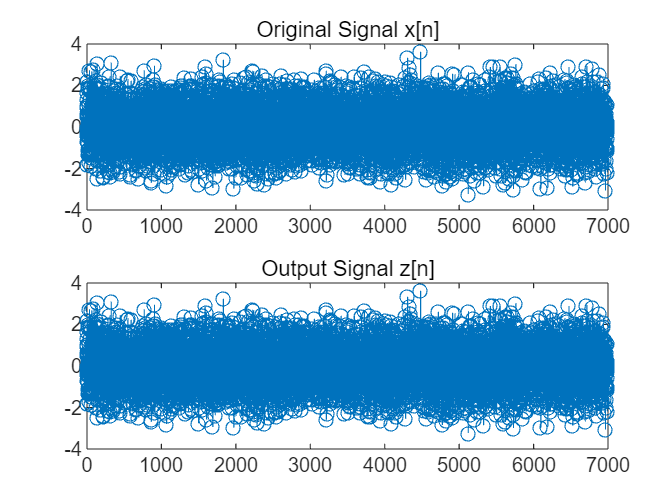

subplot(211);
stem(x);
title('Original Signal x[n]');
subplot(212);
stem(z);
title('Output Signal z[n]');